# Problema 1

## Rotacion en el eje x

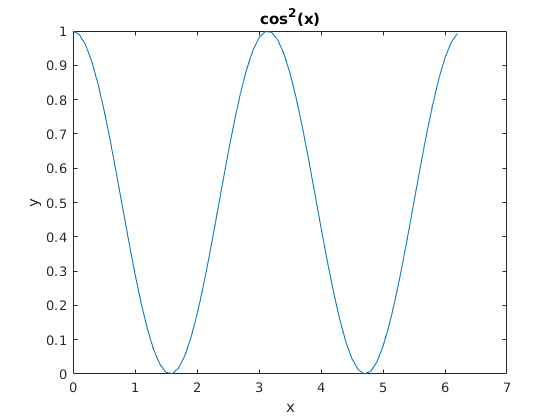

syms u v y x;

x = 0:0.1:2*pi;
y = cos(x).^2;

plot(x,y)
xlabel('x');
ylabel('y');
title('cos^2(x)');

### Parametrizacion:

syms v t;

rot_x = [1 0 0 ; 0 cos(u) -sin(u) ; 0 sin(u) cos(u)];
v = [t cos(t).^2 0];
phi = v * rot_x

$$phi = \left(\begin{array}{ccc} t & {\cos\left(t\right)}^{2}\,\cos\left(u\right) & -{\cos\left(t\right)}^{2}\,\sin\left(u\right) \end{array}\right)$$

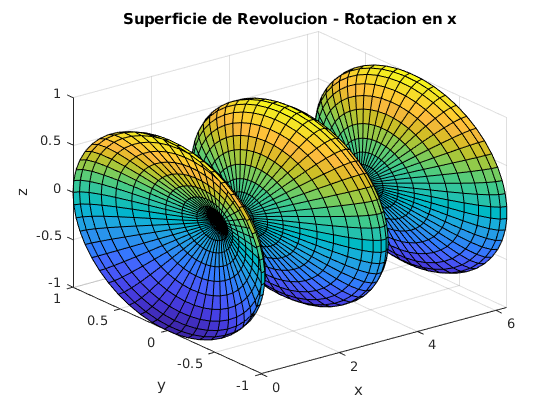

ezsurf(t,(cos(t).^2)*cos(u),(-cos(t).^2)*sin(u),[0,2*pi,0,2*pi])
title('Superficie de Revolucion - Rotacion en x')

## Rotacion en el eje y

syms v t;

rot_y = [cos(u) 0 sin(u); 0 1 0; -sin(u) 0 cos(u)];
v = [t cos(t).^2 0];
phi = v * rot_y

$$phi = \left(\begin{array}{ccc} t\,\cos\left(u\right) & {\cos\left(t\right)}^{2} & t\,\sin\left(u\right) \end{array}\right)$$

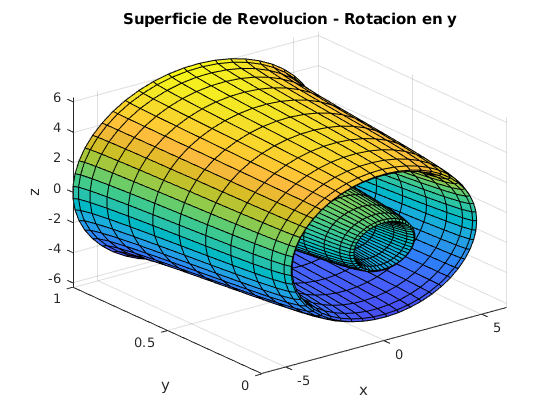

ezsurf(t*cos(u), cos(t)^2, t*sin(u),[0,2*pi,0,2*pi])
title('Superficie de Revolucion - Rotacion en y')

## Problema 2

rot_z = [cos(u) -sin(u) 0; sin(u) cos(u) 0; 0 0 1];
v = [t cos(t).^2 0];
phi = v * rot_z

$$phi = \left(\begin{array}{ccc} \sin\left(u\right)\,{\cos\left(t\right)}^{2}+t\,\cos\left(u\right) & {\cos\left(t\right)}^{2}\,\cos\left(u\right)-t\,\sin\left(u\right) & 0 \end{array}\right)$$

## Problema 3


$$y=90x^8$$


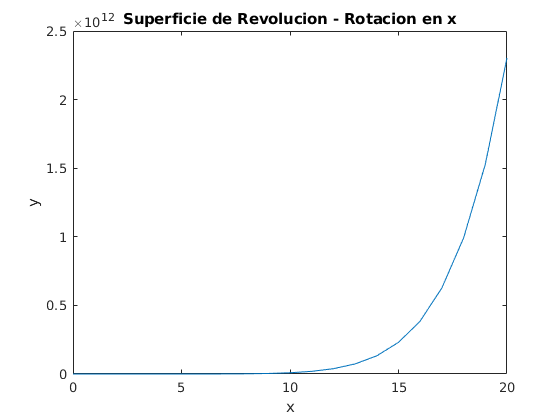

x = 0:1:20;
y = 90*x.^8;

plot(x,y)
xlabel('x');
ylabel('y');
title('y=90x^8');
title('Superficie de Revolucion - Rotacion en x')


syms v t;

rot_y = [cos(u) 0 sin(u); 0 1 0; -sin(u) 0 cos(u)];
v = [t 90*t^8 0];
phi = v * rot_y

$$phi = \left(\begin{array}{ccc} t\,\cos\left(u\right) & 90\,t^{8} & t\,\sin\left(u\right) \end{array}\right)$$

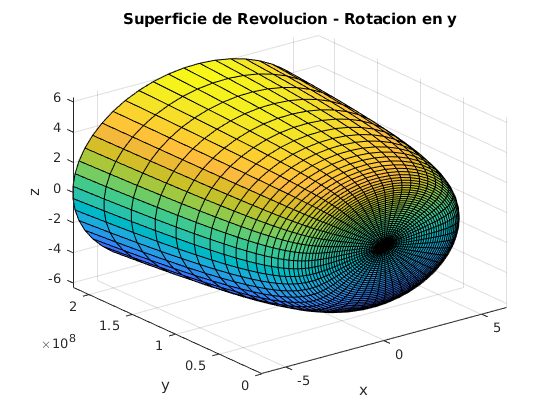

ezsurf(t*cos(u), 90*t^8, t*sin(u),[0,2*pi,0,2*pi])
title('Superficie de Revolucion - Rotacion en y')

## Problema 4

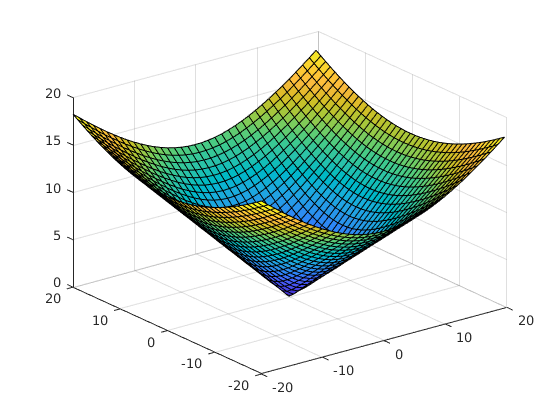

syms z y x r u;

x = -20:1.1:20;
y = -20:1:20;

[X,Y] = meshgrid(x,y);
z=sqrt(((X.^2)/2)+((Y.^2)/3));

surf(x,y,z)

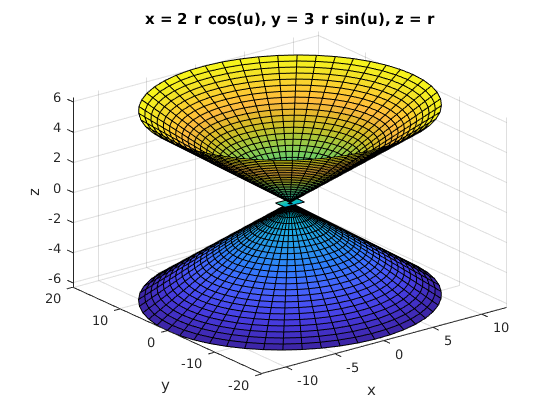

ezsurf(2*r*cos(u), 3*r*sin(u), r,[-2*pi,2*pi,0,2*pi])
patch([1 -1 -1 1], [1 1 -1 -1], [0 0 0 0], [1 1 -1 -1]); 

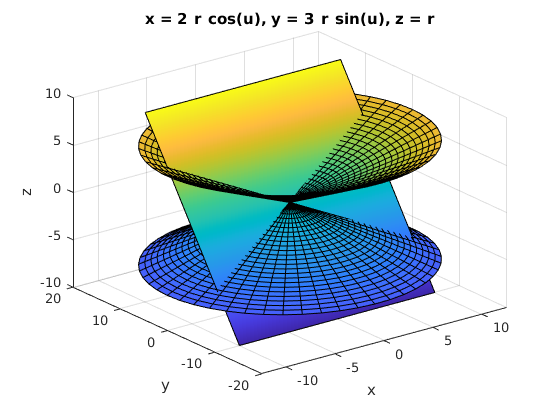

ezsurf(2*r*cos(u), 3*r*sin(u), r,[-2*pi,2*pi,0,2*pi]) % Plot the surface
patch( [10 -10 -10 10] , [10 10 -10 -10], [10 10 -10 -10], [10 10 -10 -10])

[2; 2; 3] .* [5; 5; 5]

ans =     10
    10
    15


[cos(u); sin(t); 1] .* [-2*t*sin(u); 3*t*sin(u); 0]

$$ans = \left(\begin{array}{c} -2\,t\,\cos\left(u\right)\,\sin\left(u\right)\\ 3\,t\,\sin\left(t\right)\,\sin\left(u\right)\\ 0 \end{array}\right)$$